# Design Filter with Passband and Stopband Frequencies

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a watermarked signal. For more information, see the *Generating Signals and Common Signal Operations* module.

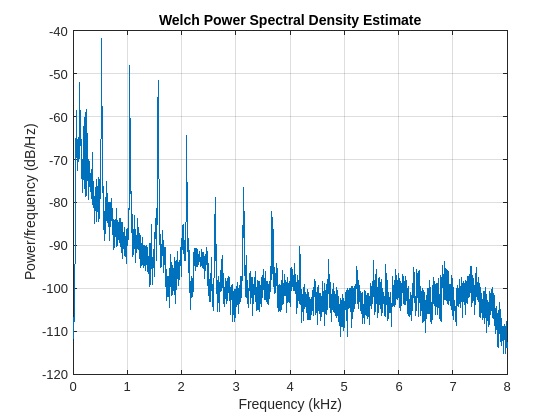

[flute,fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:3*fs);
t = ((0:numel(flute)-1)/fs)';
yin = chirp(t,2200,t(end),2500);
marked = flute + yin*0.0005;
pwelch(marked,[],[],[],fs)

## Tasks

In the previous activity, you could keep increasing the filter order until the flute harmonics will be filtered out. Or you can specify the passband and stopband frequencies instead. The result will be a filter with the smallest filter order possible that fulfills the specifications.

The two flute harmonics near the watermark are at about 2100 Hz and 2600 Hz, so the stopbands should be within those bounds.

In the power spectrum of the filtered signal, notice that the chirp watermark now has higher power than the flute signal. You can decrease the flute audio power further by increasing the amount of stopband attenuation.

The power from the flute audio at the higher frequencies is already very small, so you don't need to change **Stopband attenuation 2**. But the power from the flute audio at lower frequencies is only about 10 dB smaller than the watermark.

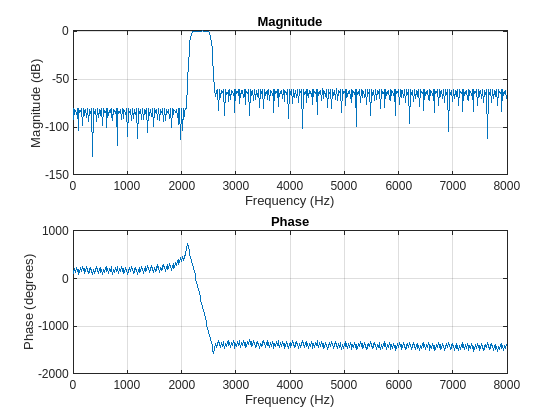

% Design a digital filter
designedFilter = designfilt('bandpassfir', ...
    'StopbandFrequency1',2100,'PassbandFrequency1',2200, ...
    'PassbandFrequency2',2500,'StopbandFrequency2',2600, ...
    'StopbandAttenuation1',80,'PassbandRipple',1, ...
    'StopbandAttenuation2',60,'SampleRate',fs);

% Visualize magnitude and phase responses
freqz(designedFilter.Coefficients,1,[],fs)

Visualize the spectrum of the filtered signal

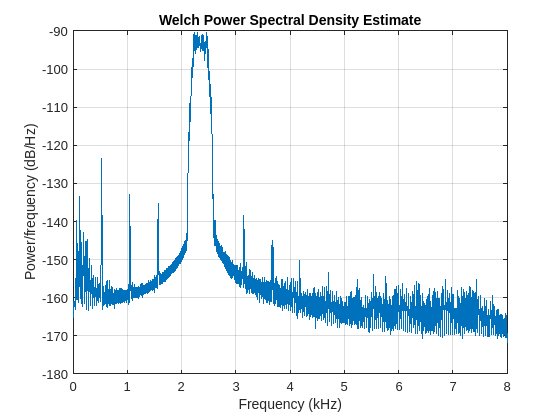

yout = filter(designedFilter,marked);
pwelch(yout,[],[],[],fs)